# Array Pattern Synthesis

This example shows how to use Phased Array System Toolbox™ to solve some array synthesis problems.

c = 3e8;        % signal propagation speed
fc = 60e9;       % signal carrier frequency
lambda = c/fc;  % wavelength

## Pattern Synthesis Using Windowing Function

A frequent problem when designing a phased array is matching a desired beam pattern to a specification that is handed to you. Often, the requirements are expressed in terms of beamwidth and sidelobe level.

The process of addressing such a problem often include these steps:

- Observe the desired pattern and decide an array geometry;

- Choose an array size based on the desired beamwidth;

- Design tapers based on the desired sidelobe level;

- Iterate on adjusting the parameter obtained step 2 and 3 to get a best match.

The following example illustrates these four steps. First, observe the desired pattern shown in the following figure.

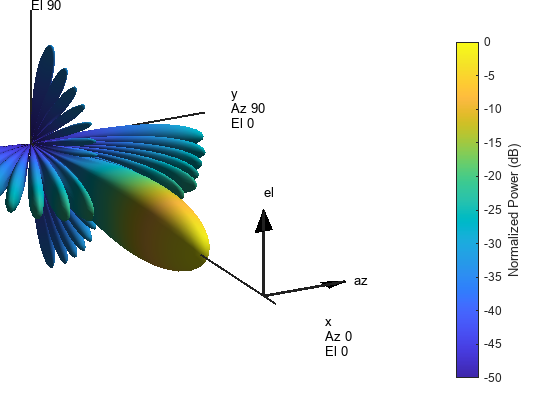

load desiredSynthesizedAntenna;

clf;
pattern(mysteryAntenna,fc,"CoordinateSystem","polar","Type","powerdb"); 
view(50,20);
ax = gca;
ax.Position = [-0.15 0.1 0.9 0.8];
camva(4.5); 
campos([520 -250 200]);

The 3D radiation patterns exhibits some symmetries in both azimuth and elevation cuts. Therefore, the pattern may be best obtained using a uniform rectangular array (URA). It is also clear from the plot that there is no energy radiated toward back of the array.

Next, determine the size of the array. To avoid grating lobes, the element spacing is set to half wavelength. For a URA, the sizes along the azimuth and elevation directions can be derived from the required beamwidths along azimuth and elevation directions, respectively. In the case of half wavelength spacing, the number of elements along a certain direction can be approximated by


$$ N \simeq \frac{2}{\sin (\theta_b)} $$


where $\theta_b$ is the beamwidth along that direction. Hence, the aperture size of the URA can be computed as

[azpat,elpat,az,el] = helperExtractSynthesisPattern(mysteryAntenna,fc,c);

% Azimuth direction
idx = find(azpat>pow2db(1/2));
azco = [az(idx(1)) az(idx(end))]; % azimuth cutoff
N_col = round(2/sind(diff(azco)))

N_col = 19


% Elevation direction
idx = find(elpat>pow2db(1/2));
elco = [el(idx(1)) el(idx(end))]; % elevation cutoff
N_row = round(2/sind(diff(elco)))

N_row = 14

The estimation suggests to start with a 14x19 URA.

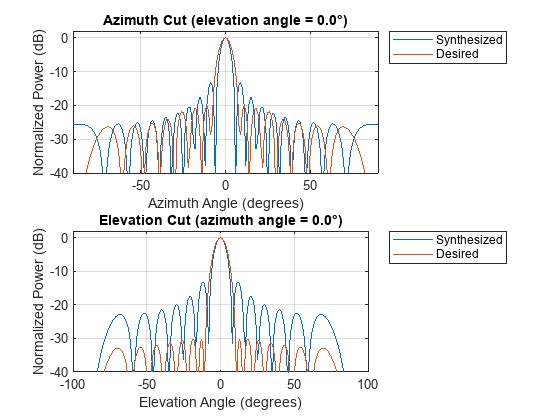

% form the URA
myURA = phased.URA([N_row N_col],[lambda/2 lambda/2]);
myURA.Element.BackBaffled = true;

helperArraySynthesisComparison(myURA,mysteryAntenna,fc,c)

The figure shows that the synthesized array exceeds the beamwidth requirement of the desired pattern. However, the sidelobes are much larger than the desired pattern. You can reduce the sidelobes by applying a windowing operation to the array. Because the URA can be considered to be the combination of two separable uniform linear arrays (ULA), the window can be designed independently along both the azimuth and elevation directions using familiar filter design methods.

The code below shows how to obtain the windows for azimuth and elevation directions.

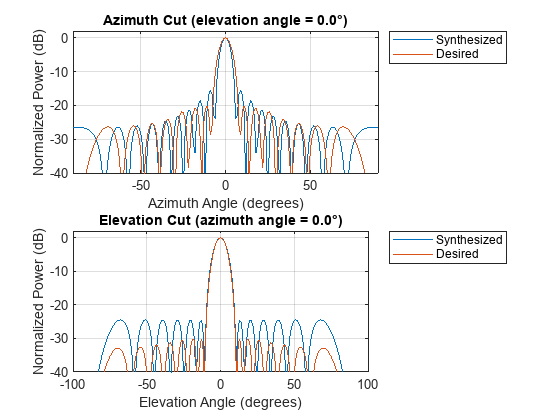

AzSidelobe = 20;                         
Ap = 0.1;                                % Passband ripples
AzWeights = designfilt("lowpassfir","FilterOrder",N_col-1,...
    "CutoffFrequency",azco(2)/90,"PassbandRipple",0.1,...
    "StopBandAttenuation",AzSidelobe);
azw = AzWeights.Coefficients;

ElSidelobe = 30;                         
ElWeights = designfilt("lowpassfir","FilterOrder",N_row-1,...
    "CutoffFrequency",elco(2)/90,"PassbandRipple",0.1,...
    "StopBandAttenuation",ElSidelobe);
elw = ElWeights.Coefficients;

% Assign the weights to the array
myURA.Taper = elw(:)*azw(:).';

% Compare the pattern
helperArraySynthesisComparison(myURA,mysteryAntenna,fc,c)

The figure shows that the resulting sidelobe level is lower compared to the previous design but still does not satisfy the requirement. By some trials and errors, the following parameters are used to create the final design:

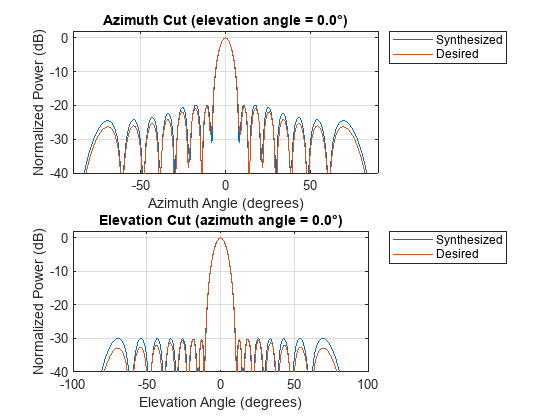

N_row = N_row+2;        % trial and error
N_col = N_col-3;        % trial and error
AzSidelobe = 26;
ElSidelobe = 35;

AzWeights = designfilt("lowpassfir","FilterOrder",N_col-1,...
    "CutoffFrequency",azco(2)/90,"PassbandRipple",0.1,...
    "StopBandAttenuation",AzSidelobe);
azw = AzWeights.Coefficients;

ElWeights = designfilt("lowpassfir","FilterOrder",N_row-1,...
    "CutoffFrequency",elco(2)/90,"PassbandRipple",0.1,...
    "StopBandAttenuation",ElSidelobe);
elw = ElWeights.Coefficients;

myURA = phased.URA([N_row N_col],[lambda/2 lambda/2]);
myURA.Element.BackBaffled = true;

myURA.Taper = elw(:)*azw(:).';

helperArraySynthesisComparison(myURA,mysteryAntenna,fc,c)

The figure shows that the beamwidth and sidelobe levels of the synthesized pattern match the desired specifications. The following figures show the desired 3D patter, the synthesized 3D pattern, the resulting array geometry, and the taper.

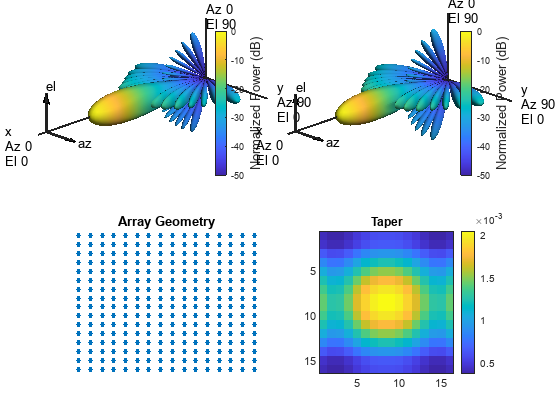

helperArraySynthesisComparison(myURA,mysteryAntenna,fc,c,"3d")

## Reference

[1] Randy L. Haupt, Thinned Arrays Using Genetic Algorithms, IEEE Transactions on Antennas and Propagation, Vol 42, No 7, 1994

[2] Randy L. Haupt, An Introduction to Genetic Algorithms for Electromagnetics, IEEE antennas and Propagation Magazine, Vol 37, No 2, 1995

[3] Harry L. Van Trees, Optimum Array Processing, Wiley-Interscience, 2002